%% Proyecto - Comunicaciones Eléctricas
% -------------------------------------------------------------------------
% Descripción:
% Este proyecto tiene como objetivo la simulación de un sistema de comunicaciones 
% eléctricas basado en modulación FM, multiplexación FDM, superheterodinaje y demodulación. 
% Se configuran señales de prueba, se realiza la modulación AM de cada tono y se implementa 
% la multiplexación de las señales moduladas. Finalmente, se analizan las 
% señales a través de su espectro en frecuencia.
% -------------------------------------------------------------------------

% -------------------------------------------------------------------------
% Parámetros Generales del Sistema
% -------------------------------------------------------------------------
% fm       - Frecuencia de modulación
% fs       - Frecuencia de muestreo del sistema (Hz)
% T        - Tiempo total de simulación (s)
% t        - Vector de tiempo de la simulación
% deltaf   - Desviación de frecuencia para sistemas de FM (no implementado aquí),
%            valor típico entre 5 y 10 veces la máxima frecuencia de mensaje.


## Configuración de parámetros


% -------------------------------------------------------------------------
% Configuración de Tono de Prueba
% -------------------------------------------------------------------------
% Am1, Am2, Am3   - Amplitudes de los tonos de prueba
% fm1, fm2, fm3   - Frecuencias de los tonos de prueba
% Cada tono representa una señal de mensaje que será modulada y multiplexada.
Am1 = 15; fm1 = 1000;      % Tono 1: Amplitud 10, Frecuencia 1 kHz
Am2 = 10; fm2 = 2000;      % Tono 2: Amplitud 10, Frecuencia 2 kHz
Am3 = 5; fm3 = 3000;      % Tono 3: Amplitud 10, Frecuencia 3 kHz

% -------------------------------------------------------------------------
% Configuración de la Portadora
% -------------------------------------------------------------------------
% Ac1, Ac2, Ac3   - Amplitudes de las portadoras
% fc1, fc2, fc3   - Frecuencias de las portadoras, calculadas en función de 
%                   la frecuencia de mensaje (10 * fm) o utilizando banda de guarda.
% 
% Estas portadoras serán utilizadas para modular cada señal de mensaje.
Ac1 = 1; fc1 = 10 * fm1;   % Portadora 1: Amplitud 1, Frecuencia 10 kHz
Ac2 = 1;                   % Portadora 2: Amplitud 1, Frecuencia calculada con banda de guarda
Ac3 = 1;                   % Portadora 3: Amplitud 1, Frecuencia calculada con banda de guarda

% -------------------------------------------------------------------------

## Parámetros de Simulación


% -------------------------------------------------------------------------
% banda_guarda - Banda de guarda entre señales moduladas para evitar interferencia (Hz)
% ancho_banda  - Ancho de banda total asignado al sistema (Hz)
% vector_fm    - Vector de frecuencias de mensaje
% vector_fc    - Vector de frecuencias de portadoras, ajustado con banda de guarda
% fcn_max      - Frecuencia de portadora máxima en el sistema
% fs           - Frecuencia de muestreo (10 veces fcn_max)
% T            - Tiempo de simulación
% t            - Vector de tiempo para simulación

banda_guarda = 10e3;        % Banda de guarda: 10 kHz
ancho_banda = 120e3;        % Ancho de banda total: 120 kHz

% Vector de frecuencias de los mensajes
vector_fm = [fm1, fm2, fm3]

vector_fm =         1000        2000        3000



% Vector de frecuencias de portadoras, ajustadas para evitar solapamiento
vector_fc = gen_fc_band_guard(vector_fm, fc1, banda_guarda, ancho_banda)

Ancho de banda total utilizado:
       64000



vector_fc =        10000       23000       38000


fcn_max = max(vector_fc);   % Frecuencia máxima de las portadoras

fs = 10 * fcn_max;          % Frecuencia de muestreo: 10 veces la portadora máxima
T = 0.02;                   % Duración de la simulación (20 ms)
t = (0:1/fs:T);             % Vector de tiempo

% -------------------------------------------------------------------------

## Generación de Señales de Mensaje (Tonos de Prueba)


% -------------------------------------------------------------------------
% mt1, mt2, mt3 - Señales de mensaje para cada tono
% vector_mensaje - Colección de los tonos de prueba, a ser utilizados en modulación

mt1 = Am1 * cos(2 * pi * fm1 * t);  % Mensaje 1
mt2 = Am2 * cos(2 * pi * fm2 * t);  % Mensaje 2
mt3 = Am3 * cos(2 * pi * fm3 * t);  % Mensaje 3

vector_mensaje = {mt1, mt2, mt3};   % Agrupación de los mensajes

% -------------------------------------------------------------------------

## Graficar Señales de Mensaje en el Tiempo

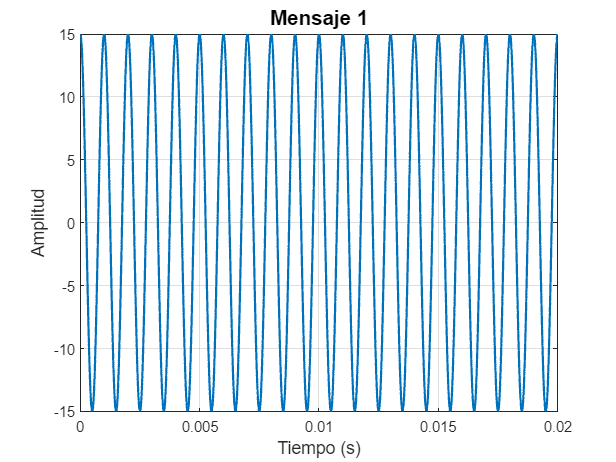


% -------------------------------------------------------------------------
plot_tiempo(mt1, t, 'Mensaje 1');

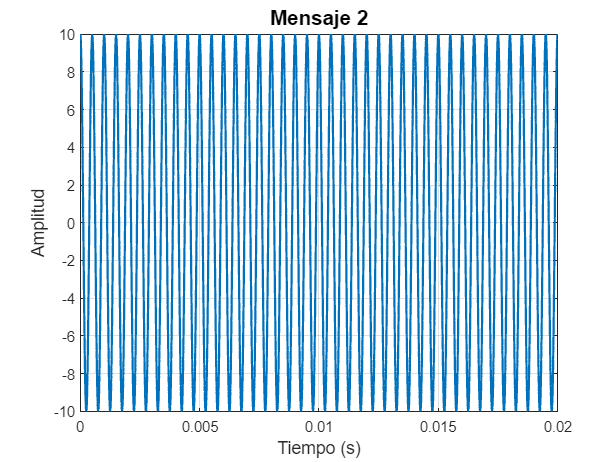

plot_tiempo(mt2, t, 'Mensaje 2');

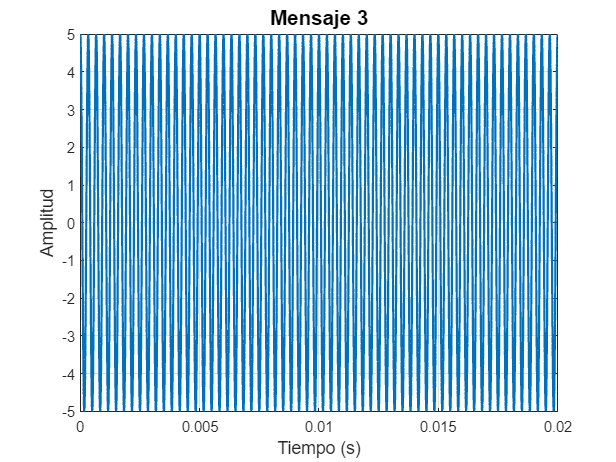

plot_tiempo(mt3, t, 'Mensaje 3');

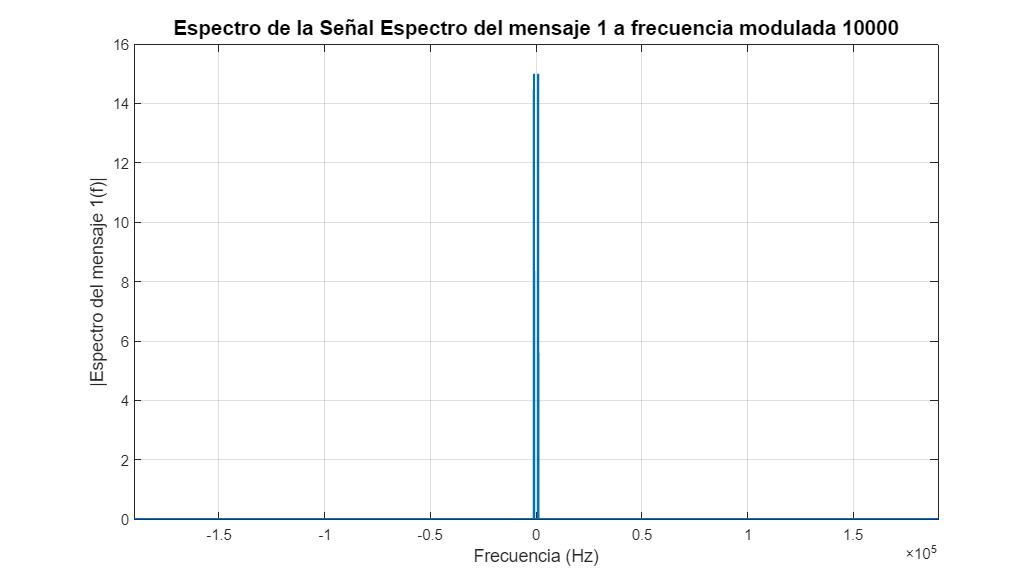


plot_espectro_completo(mt1, vector_fc(1), fs, 'Espectro del mensaje 1');

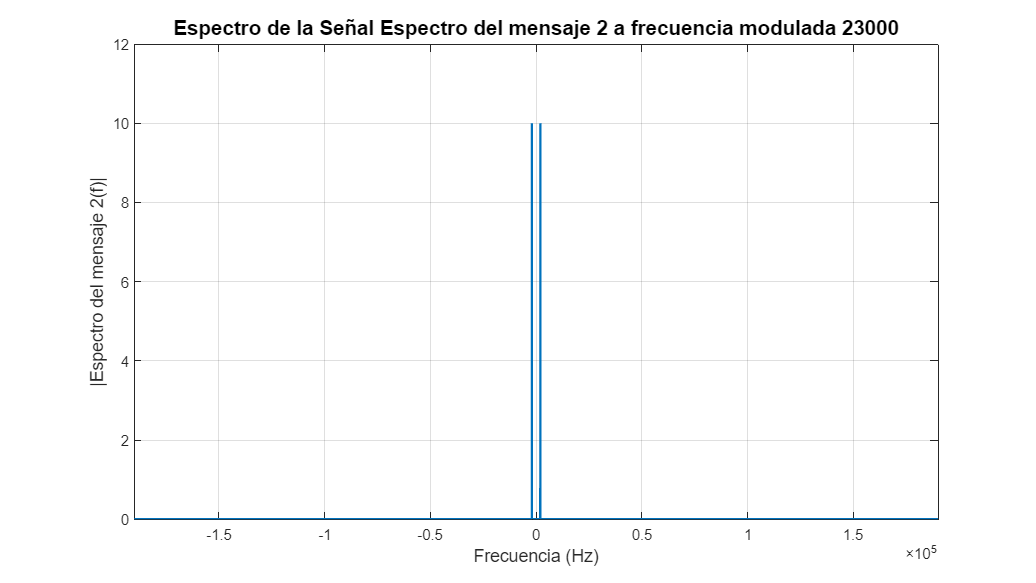

plot_espectro_completo(mt2, vector_fc(2), fs, 'Espectro del mensaje 2');

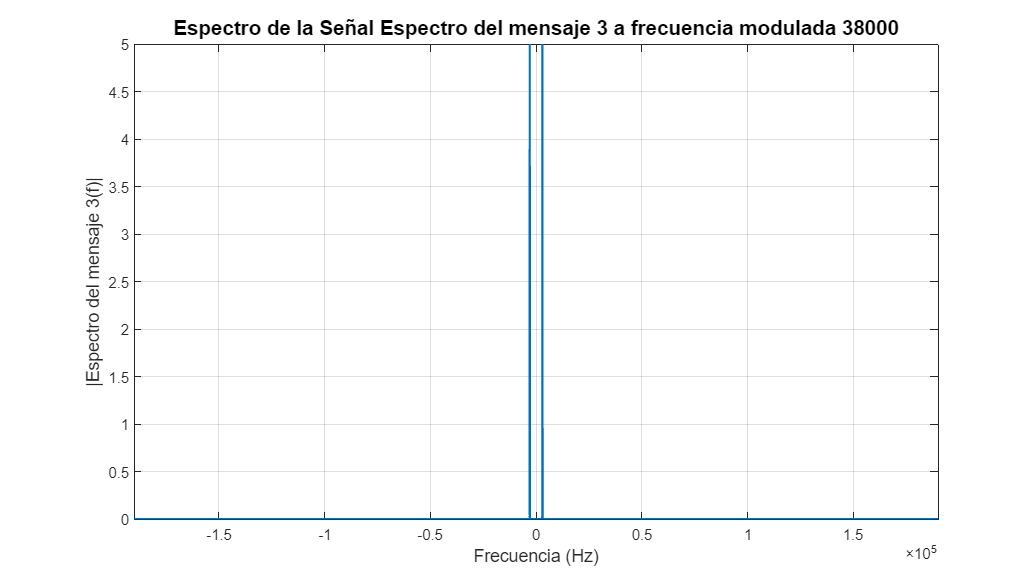

plot_espectro_completo(mt3, vector_fc(3), fs, 'Espectro del mensaje 3');


% -------------------------------------------------------------------------

## Transmisor: Modulación AM y Multiplexación FDM


% -------------------------------------------------------------------------
% Realiza la modulación AM y la multiplexación de las señales de mensaje
% utilizando las frecuencias de portadora asignadas.

% Modulación AM de cada mensaje con su respectiva portadora
fdm_celda = fdm(vector_mensaje, fs, vector_fc, vector_fm);

% -------------------------------------------------------------------------

## Graficar Espectros de Señales Moduladas

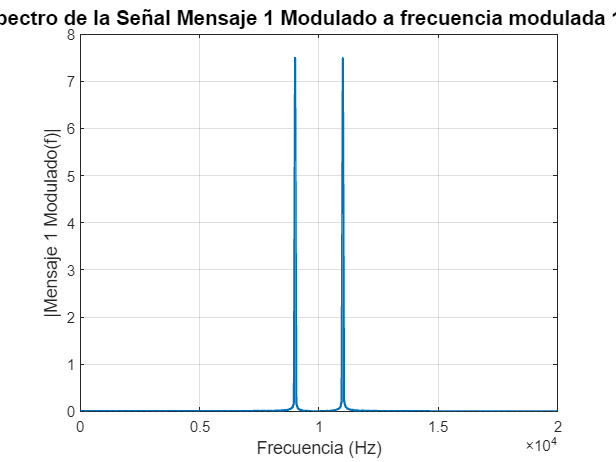


% -------------------------------------------------------------------------
% Muestra el espectro de cada señal modulada AM y la señal multiplexada total
plot_espectro(fdm_celda{2}{1}, vector_fc(1), fs, 'Mensaje 1 Modulado');

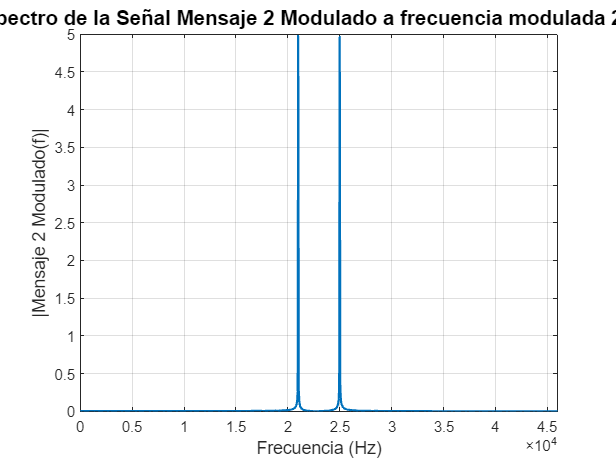

plot_espectro(fdm_celda{2}{2}, vector_fc(2), fs, 'Mensaje 2 Modulado');

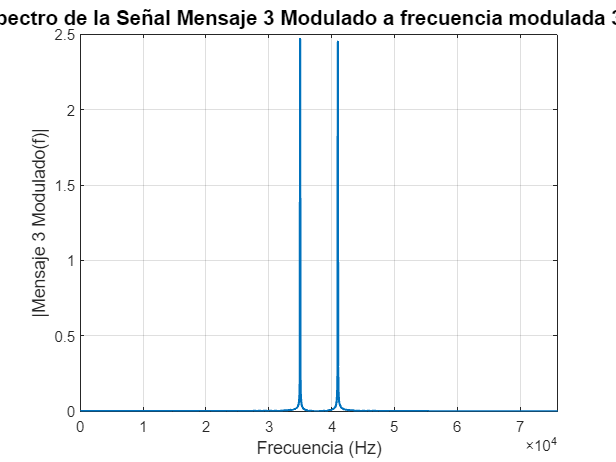

plot_espectro(fdm_celda{2}{3}, vector_fc(3), fs, 'Mensaje 3 Modulado');

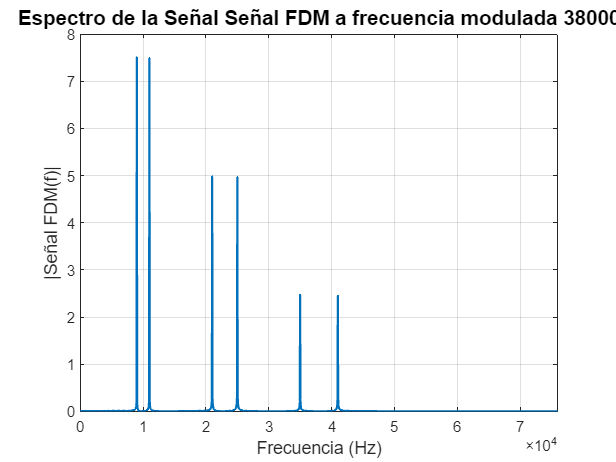


% Graficar espectro de la señal FDM completa
plot_espectro(fdm_celda{1}, fcn_max, fs, 'Señal FDM');


% -------------------------------------------------------------------------

## Implementación de la modulación FM

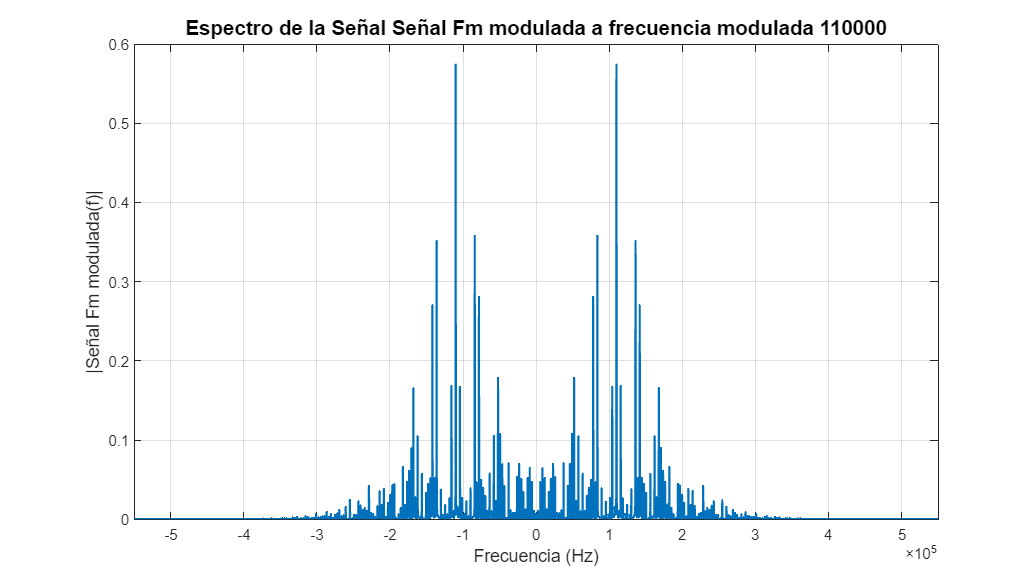


% -------------------------------------------------------------------------
%close all;
fc_mod_fm = 110e3;  % frecuencia de modulación para fm
fs_fm = 10*fc_mod_fm;   % frecuencia de muestreo para fm

freqdev = 400;
% Hecho con función modulate de matlab
fm_signal = modulate(fdm_celda{1}, fc_mod_fm, fs_fm, 'fm');
% Hecho con función fmmod de matlab
fma_signal = fmmod(fdm_celda{1}, fc_mod_fm, fs_fm, freqdev);

% plot_tiempo(fm_signal, t, 'Señal Fm modulada');
% plot_espectro(fm_signal, fc_mod_fm, 10*fc_mod_fm, 'Señal Fm modulada');
plot_espectro_completo(fm_signal, fc_mod_fm, 10*fc_mod_fm, 'Señal Fm modulada');

% plot_espectro_completo(fma_signal, fc_mod_fm, 10*fc_mod_fm, 'Señal Fm modulada opcion2');

% -------------------------------------------------------------------------

## Modelar Canal de transmisión

## Demodulación FM

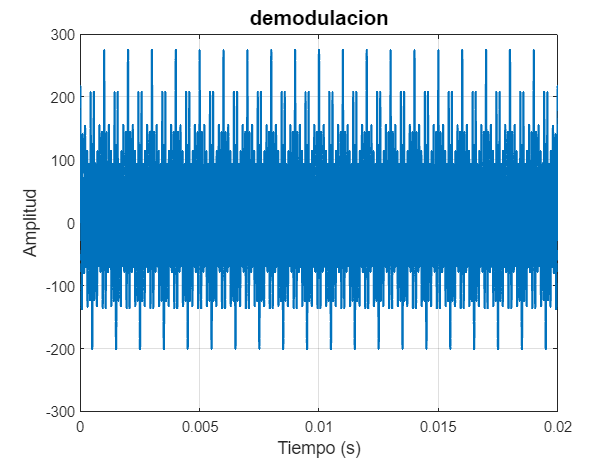

dmfm = fmdemod(fm_signal, fc_mod_fm, fs_fm, freqdev);
plot_tiempo(dmfm, t, 'demodulacion');

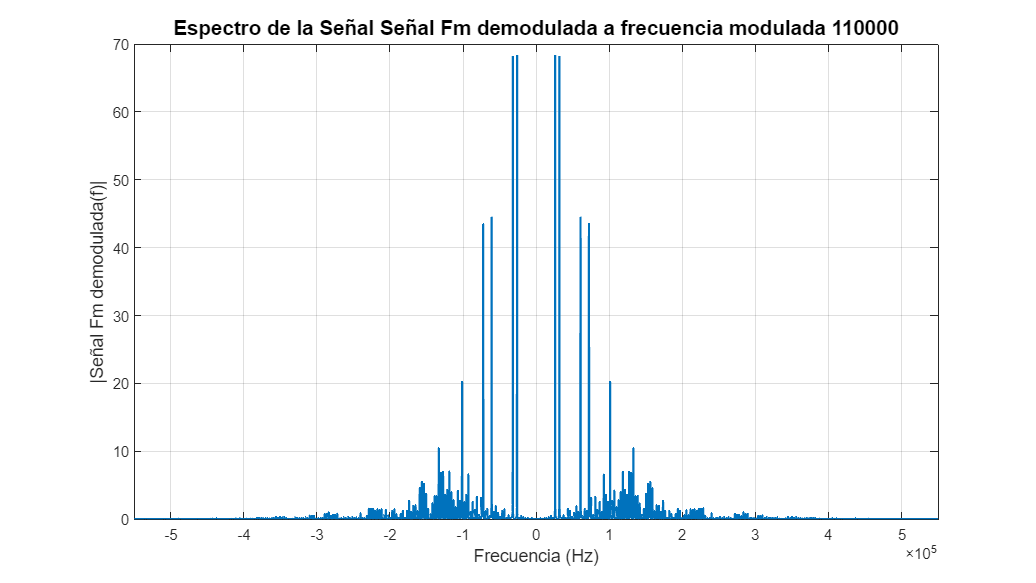

plot_espectro_completo(dmfm, fc_mod_fm, 10*fc_mod_fm, 'Señal Fm demodulada');

## Receptor


% -------------------------------------------------------------------------
% Implementación de las frecuencias portadoras para llevar la señal 
% a frecuencia intermedia
% f_portadoras = gen_fc_band_guard(vector_fm, fc1_mux, banda_guarda, 120e3)

fc1_mux = vector_fc(1)

fc1_mux = 10000

fc2_mux = vector_fc(2)

fc2_mux = 23000

fc3_mux = vector_fc(3)

fc3_mux = 38000


% Frecuencias para portadoras para el receptor
frecuencia_intermedia = 10.7e6;
fc1_receptor = frecuencia_intermedia + fc3_mux;
fc2_receptor = frecuencia_intermedia + fc2_mux;
fc3_receptor = frecuencia_intermedia + fc1_mux;
fc_receptores = [fc1_receptor, fc2_receptor, fc3_receptor]

fc_receptores =     10738000    10723000    10710000



fs_fm = 10*fc1_receptor;


## Señal 1 a la frecuencia intermedia

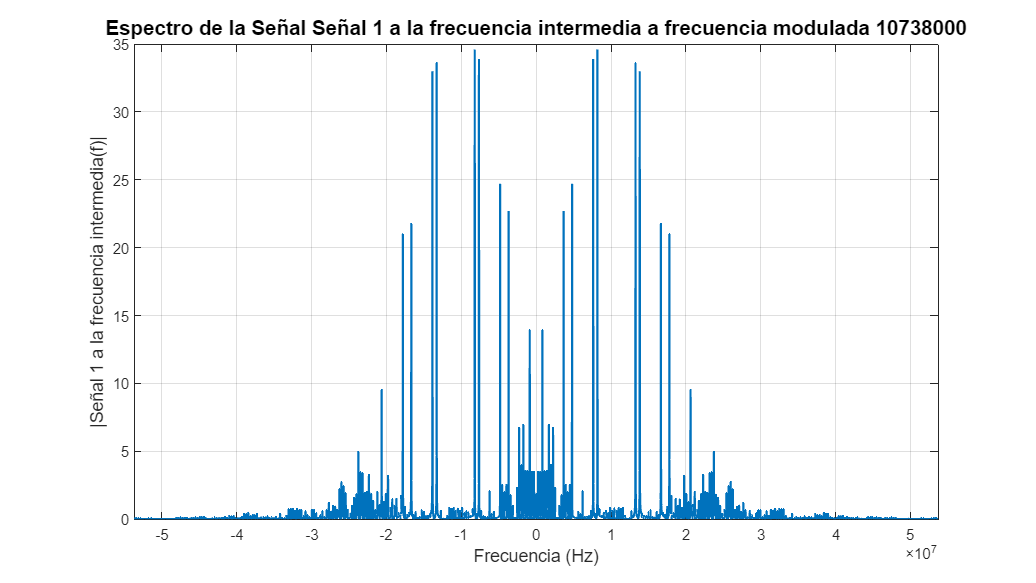


am1 = ammod(dmfm, fc1_receptor, fs_fm);
plot_espectro_completo(am1, fc1_receptor, fs_fm, 'Señal 1 a la frecuencia intermedia');

## PRUEBA

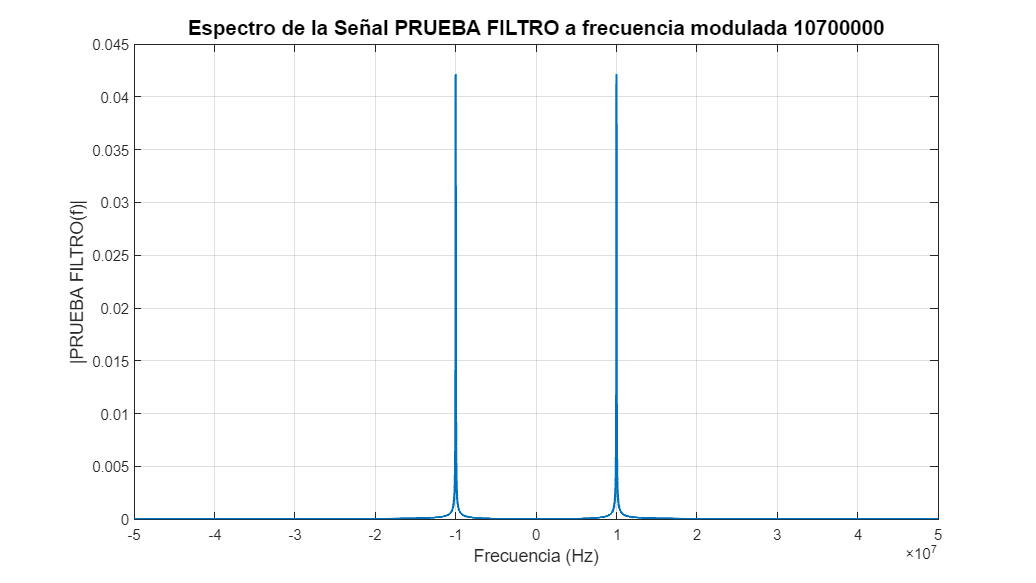


filter_signal = filtroPasoBanda(am1, frecuencia_intermedia, 1, 10*frecuencia_intermedia);
plot_espectro_completo(filter_signal, frecuencia_intermedia, fs_mux, 'PRUEBA FILTRO');

## Señal 2 a la frecuencia intermedia

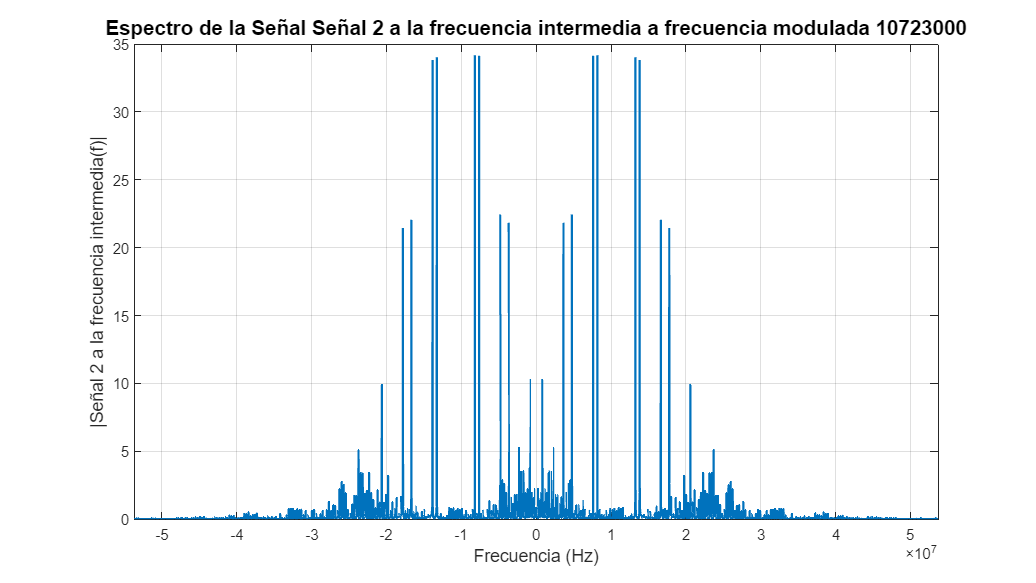


am2 = ammod(dmfm, fc2_receptor, fs_fm);
plot_espectro_completo(am2, fc2_receptor, fs_fm, 'Señal 2 a la frecuencia intermedia');

## PRUEBA

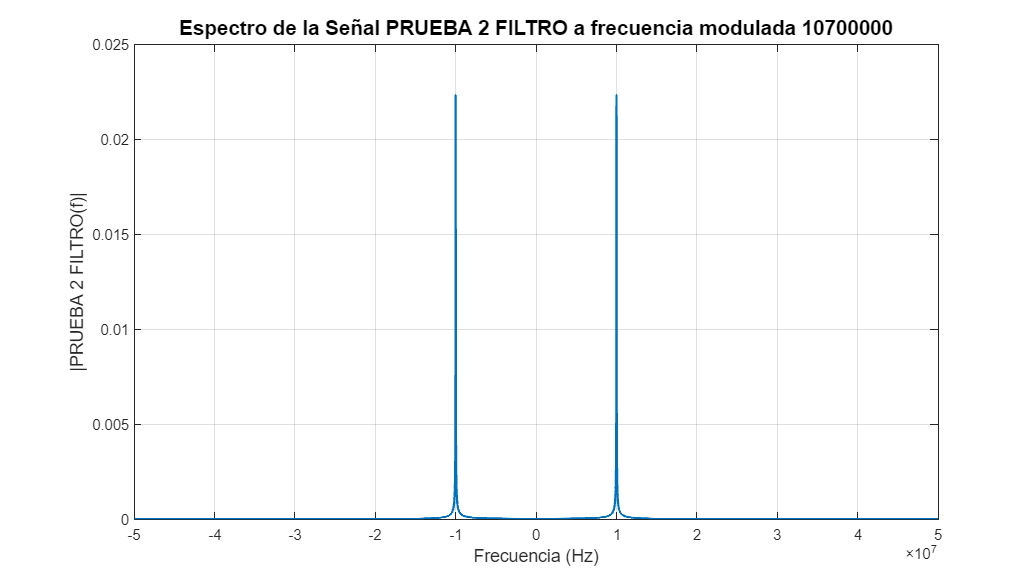


filter_signal = filtroPasoBanda(am2, frecuencia_intermedia, 1, 10*frecuencia_intermedia);
plot_espectro_completo(filter_signal, frecuencia_intermedia, fs_mux, 'PRUEBA 2 FILTRO');

## Señal 3 a la frecuencia intermedia

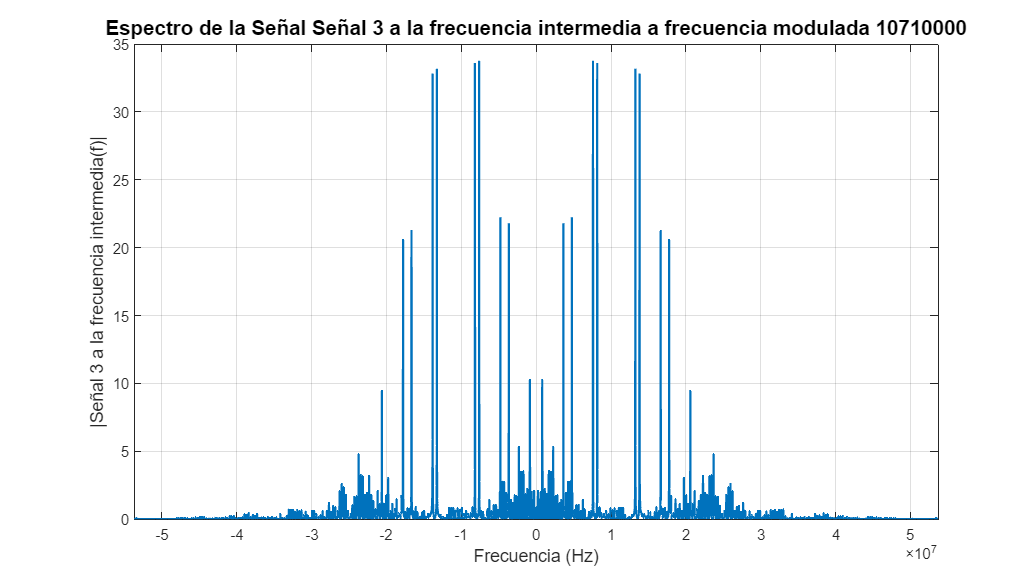


am3 = ammod(dmfm, fc3_receptor, fs_fm);
plot_espectro_completo(am3, fc3_receptor, fs_fm, 'Señal 3 a la frecuencia intermedia');

## PRUEBA 3

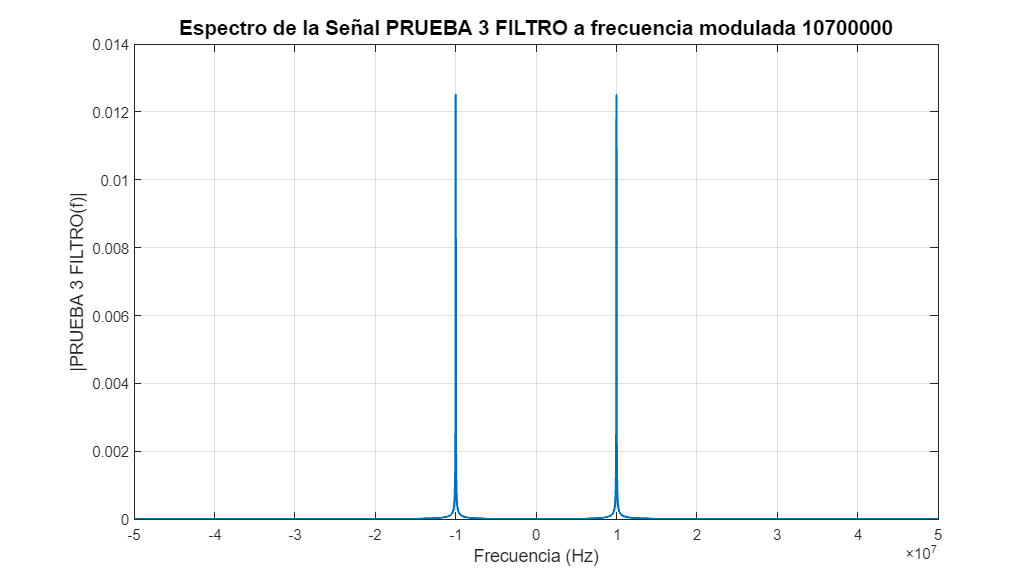

filter_signal = filtroPasoBanda(am3, frecuencia_intermedia, 1, 10*frecuencia_intermedia);
plot_espectro_completo(filter_signal, frecuencia_intermedia, fs_mux, 'PRUEBA 3 FILTRO');

## Usando la función filter_passband

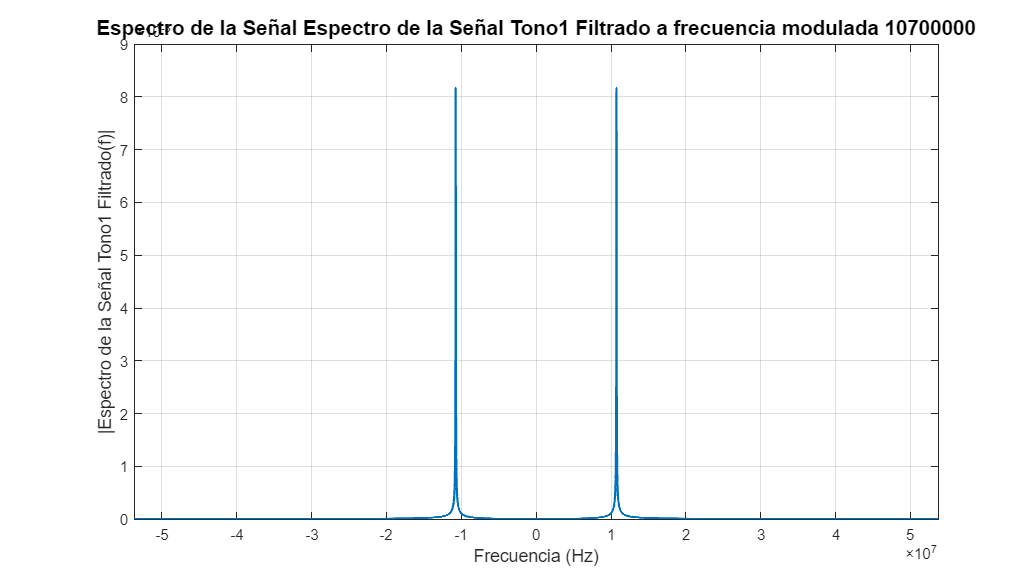


tono1_filtrado = filter_passband(am1, frecuencia_intermedia, banda_guarda);
tono2_filtrado = filter_passband(am2, frecuencia_intermedia, banda_guarda);
tono3_filtrado = filter_passband(am3, frecuencia_intermedia, banda_guarda);

plot_espectro_completo(tono1_filtrado, fi, fs_fm, 'Espectro de la Señal Tono1 Filtrado');

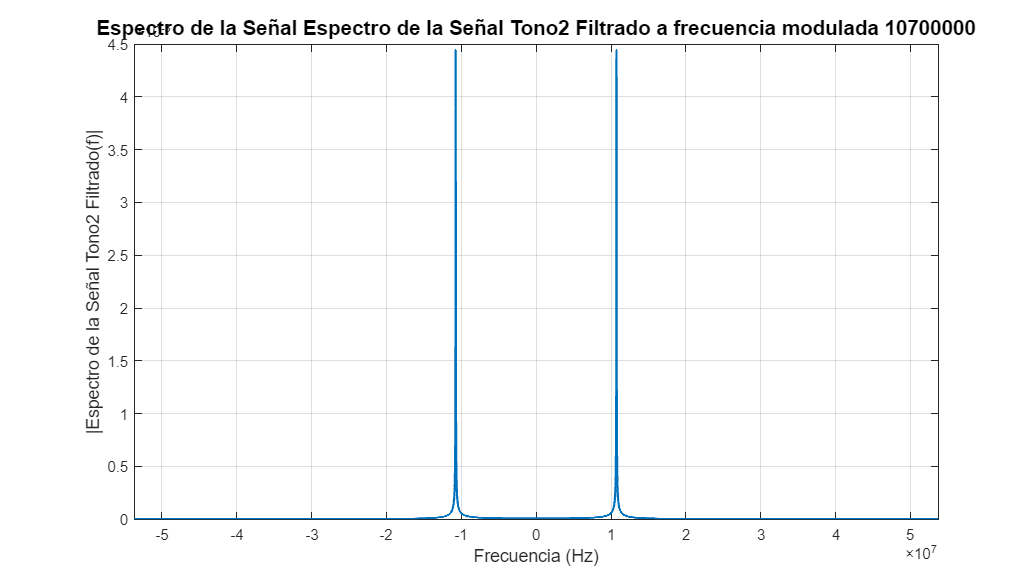

plot_espectro_completo(tono2_filtrado, fi, fs_fm, 'Espectro de la Señal Tono2 Filtrado');

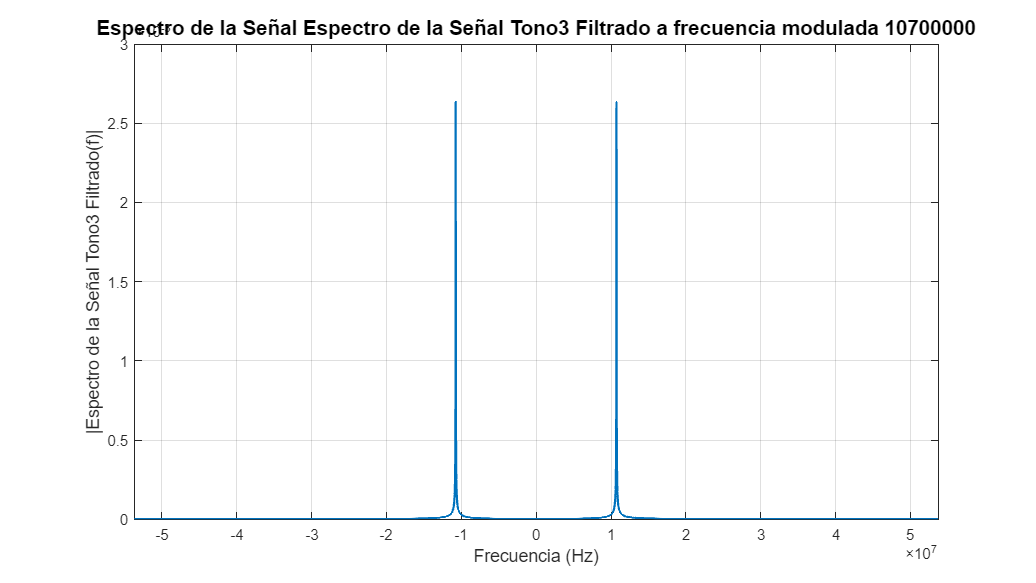

plot_espectro_completo(tono3_filtrado, fi, fs_fm, 'Espectro de la Señal Tono3 Filtrado');

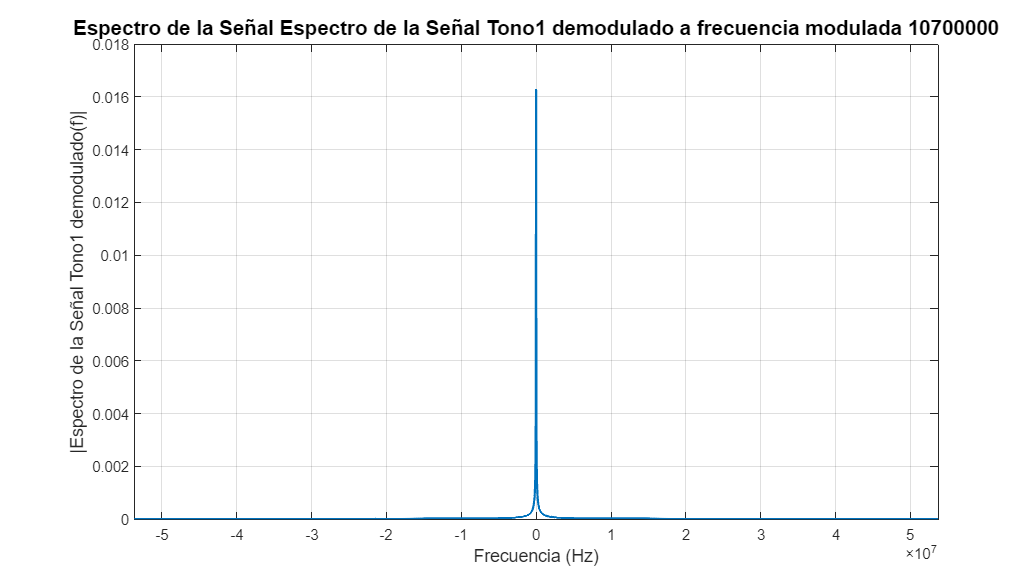


%% demodulacion tono1_filtrado
am_demod1 = amdemod(tono1_filtrado, fc1_receptor, fs_fm);
plot_espectro_completo(am_demod1, fi, fs_fm, 'Espectro de la Señal Tono1 demodulado');

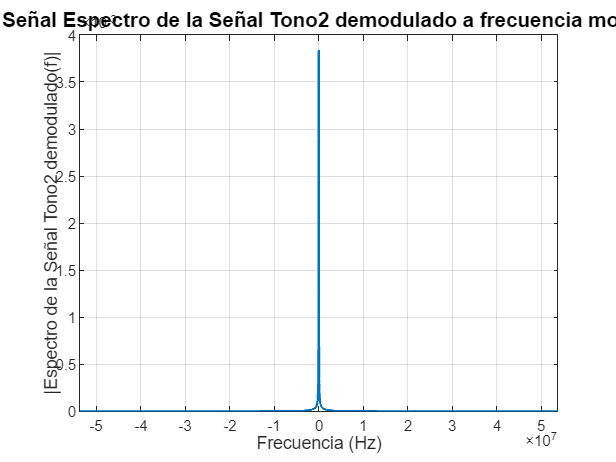


%% demodulacion tono2_filtrado
am_demod2 = amdemod(tono2_filtrado, fc2_receptor, fs_fm);
plot_espectro_completo(am_demod2, fi, fs_fm, 'Espectro de la Señal Tono2 demodulado');

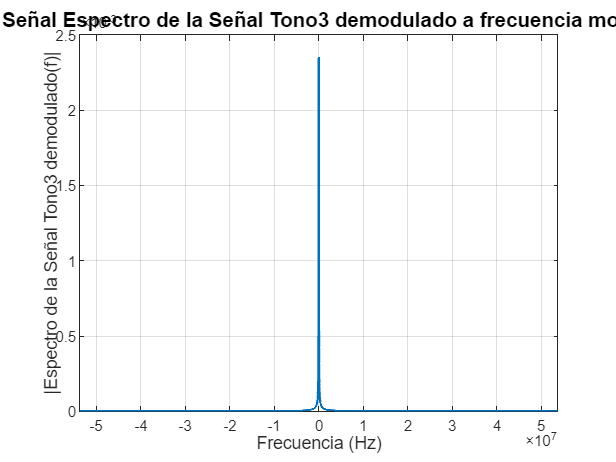


%% demodulacion tono3_filtrado
am_demod3 = amdemod(tono3_filtrado, fc3_receptor, fs_fm);
plot_espectro_completo(am_demod3, fi, fs_fm, 'Espectro de la Señal Tono3 demodulado');

## Receptor Superheterodino OPCION 2


% -------------------------------------------------------------------------

% Simulación del receptor superheterodino

## Paso 1: Demodulación FM

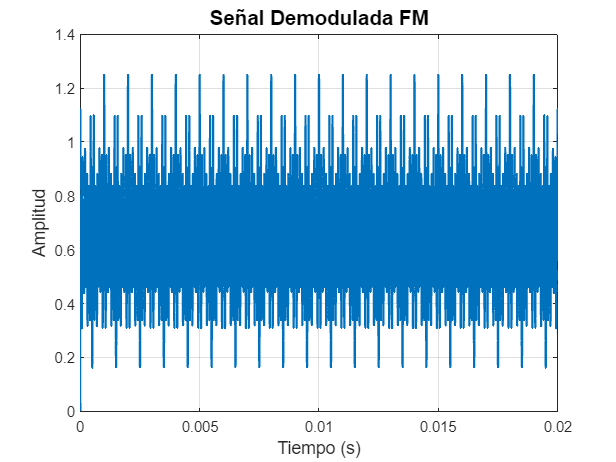


demod_signal = demod(fm_signal, fc_mod_fm, fs_fm, 'fm');
demod_signala = demod(fma_signal, fc_mod_fm, fs_fm, 'fm');

% Graficar la señal demodulada
plot_tiempo(demod_signal, t, 'Señal Demodulada FM');

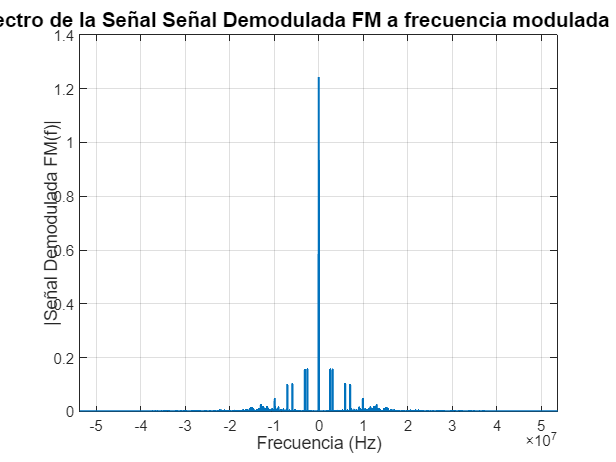

plot_espectro_completo(demod_signal, fc_mod_fm, fs_fm, 'Señal Demodulada FM');

## Paso 2: Conversión a Frecuencia Intermedia (FI)

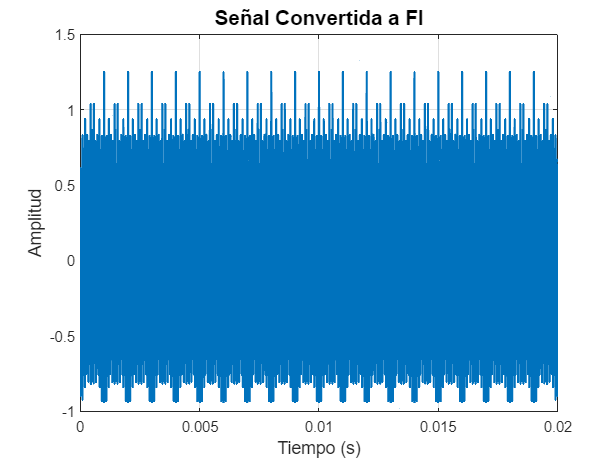


% Aquí simulamos la mezcla para pasar a una frecuencia intermedia de 10.7 MHz
fi = 10.7e6; % Frecuencia intermedia
% Generamos la señal de mezcla
mix_signal = demod_signal .* cos(2 * pi * fi * t);
mix_signala = demod_signala .* cos(2 * pi * fi * t);
plot_tiempo(mix_signal, t, 'Señal Convertida a FI');

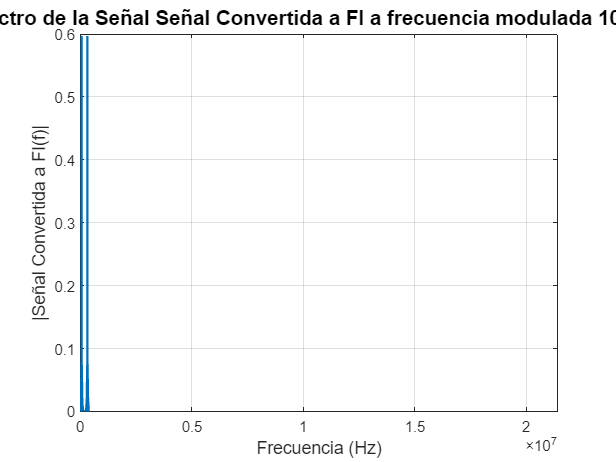

plot_espectro(mix_signal, fi, fs, 'Señal Convertida a FI');

## Paso 3: Filtro pasa banda para cada señal de audio

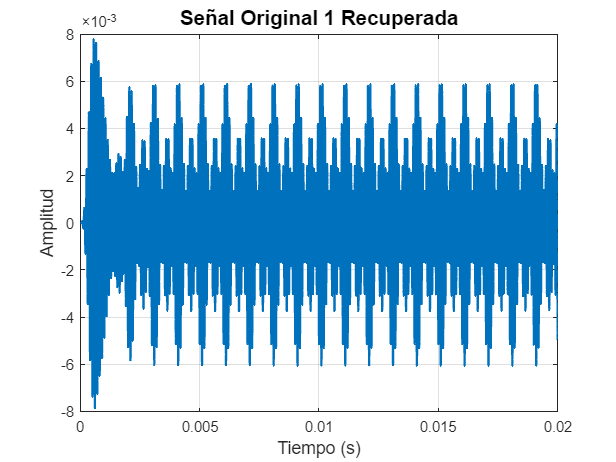


% Suponemos que las señales están centradas en las frecuencias de portadora originales
% Utilizamos filtros pasa banda para recuperar cada señal

% Generamos filtros pasa banda para cada señal
[b1, a1] = butter(5, [fc1-1e3, fc1+1e3]/(fs/2), 'bandpass');
[b2, a2] = butter(5, [vector_fc(2)-5e3, vector_fc(2)+5e3]/(fs/2), 'bandpass');
[b3, a3] = butter(5, [vector_fc(3)-5e3, vector_fc(3)+5e3]/(fs/2), 'bandpass');

% Filtramos cada componente
rec_signal1 = filter(b1, a1, mix_signal);
rec_signal2 = filter(b2, a2, mix_signala);
rec_signal3 = filter(b3, a3, mix_signala);

% Graficamos las señales recuperadas
plot_tiempo(rec_signal1, t, 'Señal Original 1 Recuperada');

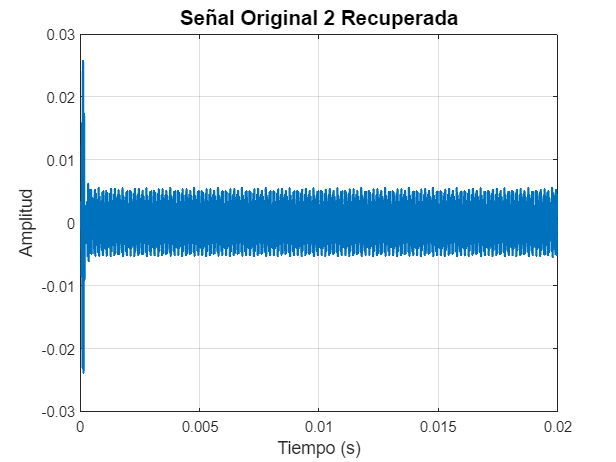

plot_tiempo(rec_signal2, t, 'Señal Original 2 Recuperada');

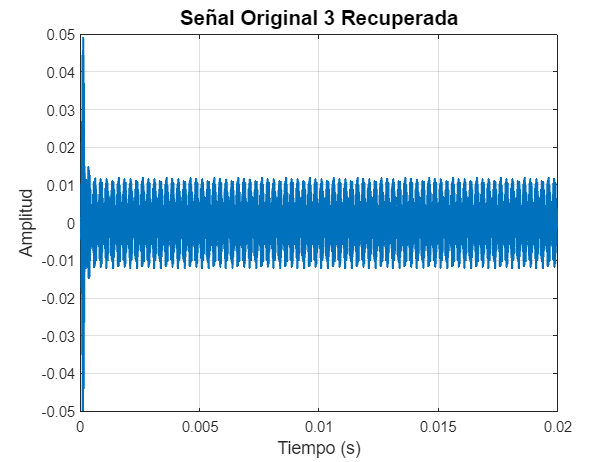

plot_tiempo(rec_signal3, t, 'Señal Original 3 Recuperada');

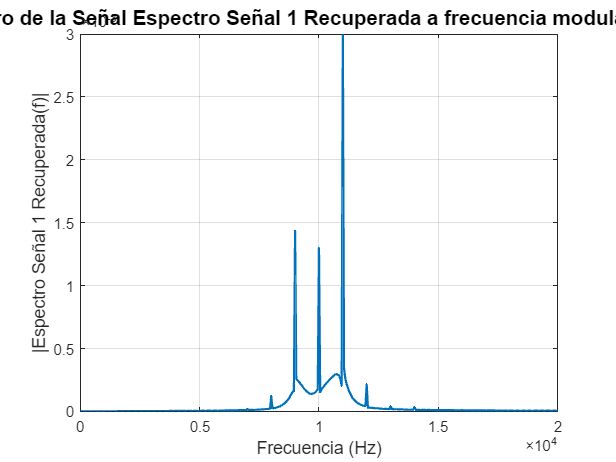


plot_espectro(rec_signal1, vector_fc(1), fs, 'Espectro Señal 1 Recuperada');

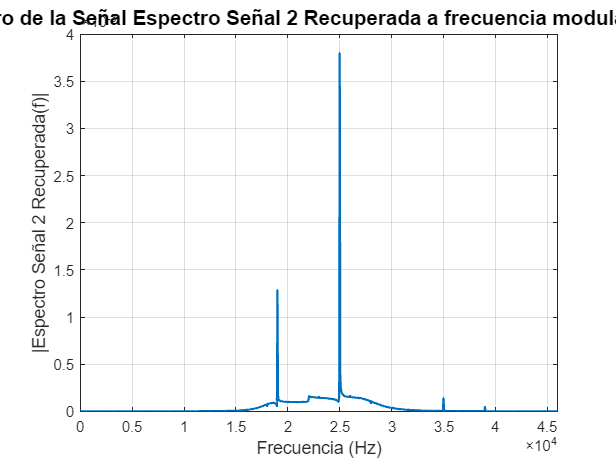

plot_espectro(rec_signal2, vector_fc(2), fs, 'Espectro Señal 2 Recuperada');

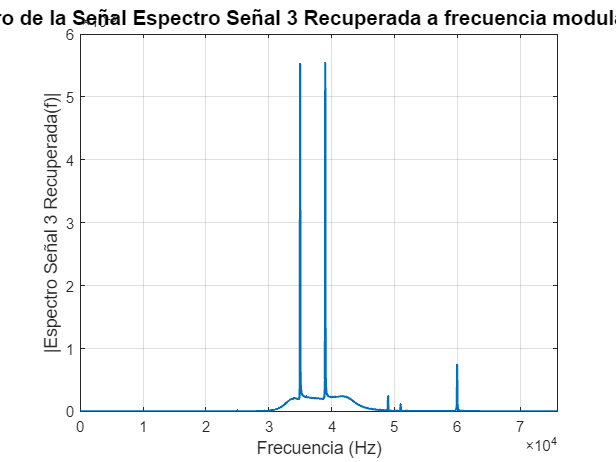

plot_espectro(rec_signal3, vector_fc(3), fs, 'Espectro Señal 3 Recuperada');

## Recuperación del mensaje original

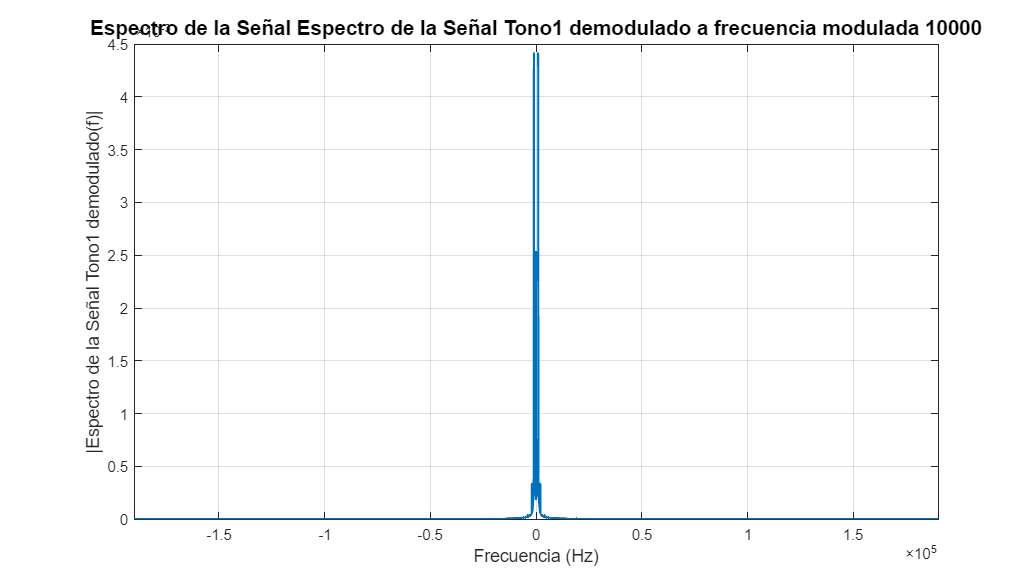

%% demodulacion tono1_filtrado
am_demoda = amdemod(rec_signal1, vector_fc(1), fs);
plot_espectro_completo(am_demoda, vector_fc(1), fs, 'Espectro de la Señal Tono1 demodulado');

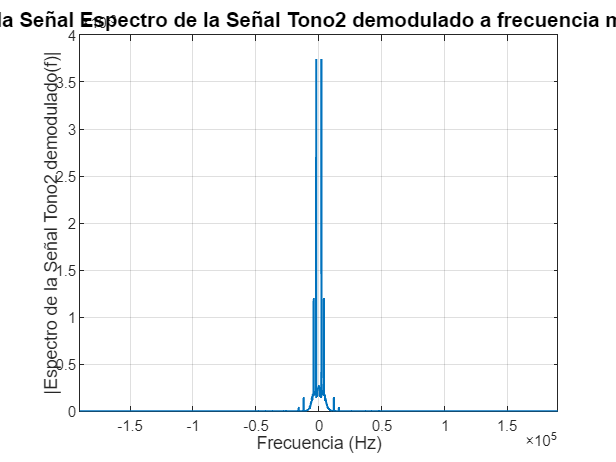


%% demodulacion tono2_filtrado
am_demodb = amdemod(rec_signal2, vector_fc(2), fs);
plot_espectro_completo(am_demodb, vector_fc(1), fs, 'Espectro de la Señal Tono2 demodulado');

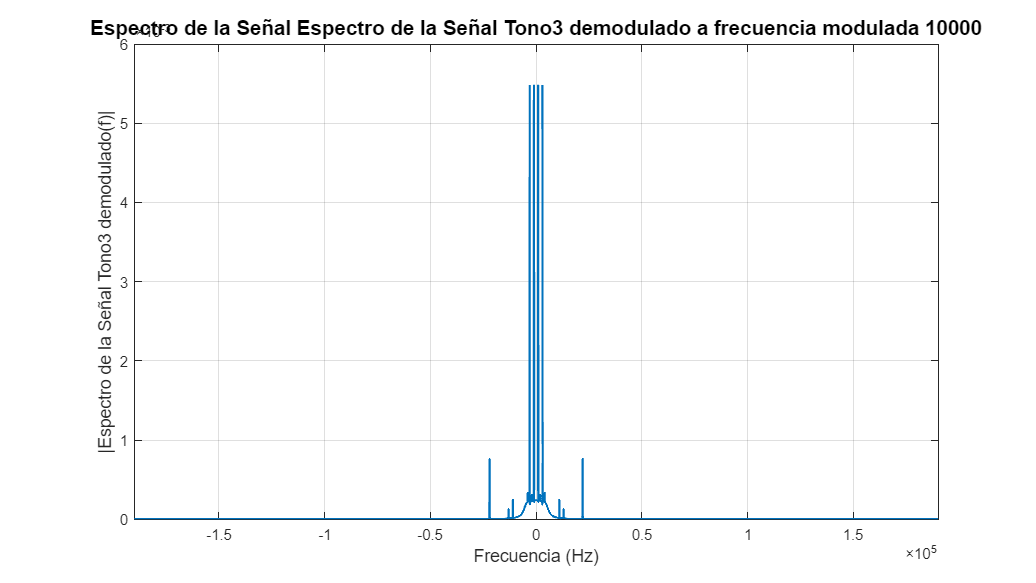


%% demodulacion tono3_filtrado
am_demodc = amdemod(rec_signal3, vector_fc(3), fs);
plot_espectro_completo(am_demodc, vector_fc(1), fs, 'Espectro de la Señal Tono3 demodulado');

## PRUEBA OUT SIGNAL

% plot_espectro_completo(out.fdm_mod_simulink_fc1,fc1_receptor, 10*fs_fm , 'TEST OUT');


% fdm_mod_simulink_fc1 = out.fdm_mod_simulink_fc1;
% filter_signal = filtroPasoBanda(fdm_mod_simulink_fc1, frecuencia_intermedia, 1, 10*fs_mux);
% plot_espectro_completo(filter_signal, frecuencia_intermedia, fs_mux, 'PRUEBA 1 FILTRO');


## PRUEBA OUT SIGNAL 2

% plot_espectro_completo(out.fdm_mod_simulink_fc2,fc1_receptor, 10*fs_fm , 'TEST OUT');

% fdm_mod_simulink_fc2 = out.fdm_mod_simulink_fc2;
% filter_signal = filtroPasoBanda(fdm_mod_simulink_fc2, frecuencia_intermedia, 1, 10*fs_mux);
% plot_espectro_completo(filter_signal, frecuencia_intermedia, fs_mux, 'PRUEBA 2 FILTRO');


## PRUEBA OUT SIGNAL 3


% plot_espectro_completo(out.fdm_mod_simulink_fc3,fc1_receptor, 10*fs_fm , 'TEST OUT');

% fdm_mod_simulink_fc3 = out.fdm_mod_simulink_fc3;
% filter_signal = filtroPasoBanda(fdm_mod_simulink_fc3, frecuencia_intermedia, 1, 10*fs_mux);
% plot_espectro_completo(filter_signal, frecuencia_intermedia, fs_mux, 'PRUEBA 3 FILTRO');


## Bibliografía